eye1 = imread("eye1.jpg")

eye1 = 395×396×3 uint8 array
eye1(:,:,1) =

   214   214   215   215   215   216   217   218   216   217   217   215   217   221   224   225   221   220   220   224   228   230   228   225   225   227   227   225   221   217   214   213   211   217   221   220   222   225   225   222   219   221   220   220   220   221   224   226   227   228   228   226   219   215   213   213   214   212   210   210   210   212   213   214   211   212   213   213   211   211   211   212   216   217   220   222   224   224   223   222   221   219   216   214   217   220   218   213   214   216   218   216   213   212   213   214   211   210   207   203   203   206   206   205   206   205   205   203   202   201   200   200   200   200   199   198   197   196   196   196   197   198   197   197   197   196   196   196   197   195   192   191   190   191   190   189   187   188   189   188   186   185   184   184   188   188   187   186   187   188   187   183   183   184   184   182   181   180   181  

eye2 = imread("eye2.jpg")

eye2 = 493×493×3 uint8 array
eye2(:,:,1) =

   173   158   122   111   109   125   131   127   125   126   118   135   152   144   149   168   172   172   180   174   176   185   180   180   172   176   177   153   163   148   150   144   138   143   149   143   135   146   170   180   185   178   179   188   192   183   183   192   175   179   178   180   185   177   166   160   150   132   118   120   130   137   142   149   135   122   133   148   160   174   170   167   167   155   151   143   143   151   159   173   166   142   119   121   119   119   114   120   126   143   167   178   180   178   180   184   175   177   179   175   170   163   162   162   166   163   163   156   160   162   174   179   187   189   188   183   187   188   190   199   188   192   188   187   192   190   186   190   187   187   190   190   192   191   189   186   183   190   187   193   192   187   194   191   189   193   200   199   192   197   202   195   192   197   198   194   194   197   196  

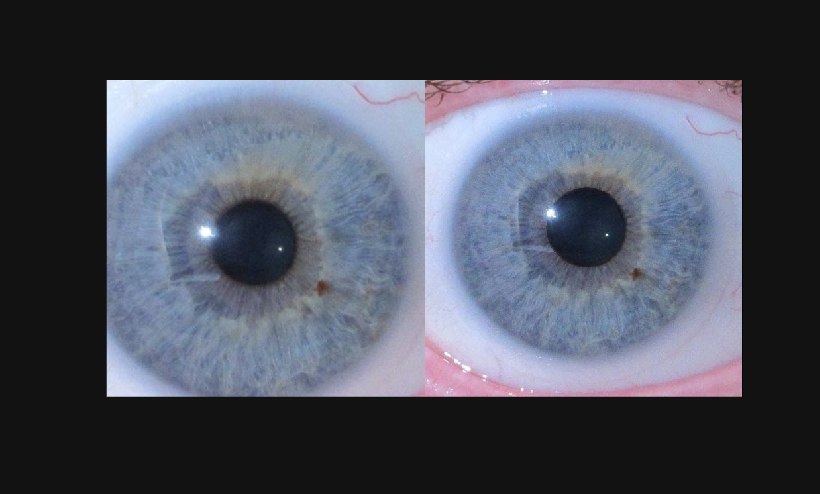

montage({eye1, eye2})


reg= registerImages(eye1 , eye2 )

reg = struct with fields:
     FixedMatchedFeatures: [78×1 SURFPoints]
    MovingMatchedFeatures: [78×1 SURFPoints]
           Transformation: [1×1 rigidtform2d]
          RegisteredImage: [493×493×3 uint8]
            SpatialRefObj: [1×1 imref2d]


imtool(reg.RegisteredImage)
imtool(eye2)


im1 = 395×396 uint8 matrix
   224   224   225   225   225   226   227   228   226   227   227   225   227   231   234   235   231   230   230   234   238   240   238   235   235   237   237   235   231   227   224   223   222   228   232   231   233   236   236   233   230   232   233   233   233   234   236   238   238   239
   225   226   226   227   226   226   227   228   226   227   227   227   229   232   234   233   230   231   233   237   240   240   236   232   227   229   231   230   228   224   222   222   223   227   229   228   229   234   235   234   231   230   230   230   230   231   232   232   227   228
   227   227   228   229   228   228   228   228   227   227   228   228   230   232   232   230   231   231   233   236   238   237   233   229   226   227   230   230   229   226   224   222   224   226   226   224   226   230   233   233   233   231   229   228   229   229   228   227   222   222
   227   228   230   230   230   230   230   230   230   230   230   2

im2 = 493×493 uint8 matrix
   159   144   107    94    91   104   109   103    98    99    91   108   125   117   122   143   151   152   160   154   155   164   159   159   150   154   155   131   139   124   126   122   116   122   128   122   113   124   146   156   158   151   151   160   163   154   154   164   147   152
   142   124    88    79    73    78    83    83    99   123   127   132   142   140   144   152   154   153   159   156   160   164   149   141   133   130   121   110   111   113   119   123   126   130   138   139   137   145   154   152   157   156   159   161   155   146   148   158   155   158
    85    84    72    75    64    62    73    86   117   152   162   161   166   165   163   159   156   153   154   148   145   143   128   118   105   103    97   108   103   119   124   133   128   132   142   149   151   160   164   158   159   161   164   162   155   151   155   159   152   155
    65    75    73    77    62    59    70    83   108   129   134   1